# Questão 4

s = tf('s')

s =
 
  s
 
Continuous-time transfer function.
Model Properties


Gp = 0.2/(2*(s+0.2))

Gp =
 
     0.2
  ---------
  2 s + 0.4
 
Continuous-time transfer function.
Model Properties



G_zpk = zpk(Gp)

G_zpk =
 
    0.1
  -------
  (s+0.2)
 
Continuous-time zero/pole/gain model.
Model Properties


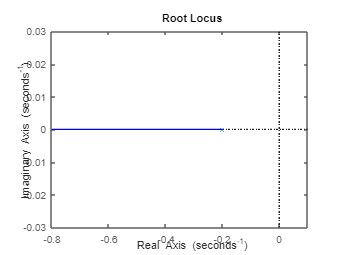


rlocus(Gp);

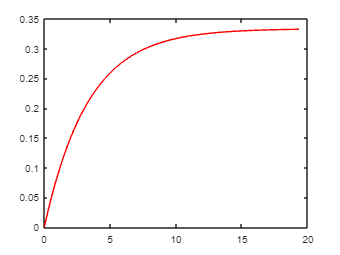

[y, tOut] = step(feedback(Gp, 1));
plot(tOut, y, color='red');

# Controlador

K = 67.059;
Gc = K * (s + 8.276);
GC_zpk = zpk(Gc)

GC_zpk =
 
  67.059 (s+8.276)
 
Continuous-time zero/pole/gain model.
Model Properties


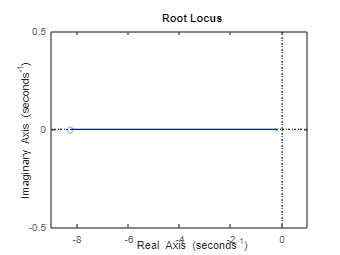

figure;
rlocus(Gp*Gc);

#  Polos em malha fechada

FT_cl = feedback(Gp * Gc, 1)

FT_cl =
 
   13.41 s + 111
  ---------------
  15.41 s + 111.4
 
Continuous-time transfer function.
Model Properties


FT_cl_zpk = zpk(FT_cl)

FT_cl_zpk =
 
  0.87023 (s+8.276)
  -----------------
      (s+7.228)
 
Continuous-time zero/pole/gain model.
Model Properties


pole(FT_cl_zpk)

ans = -7.2280

zero(FT_cl_zpk)

ans = -8.2760

# Resposta ao degrau

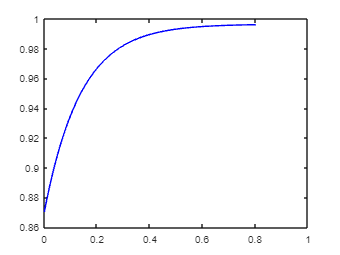

[y_cl, tOut_cl] = step(FT_cl);
plot(tOut_cl, y_cl, color='blue');

# Diagrama de Bode

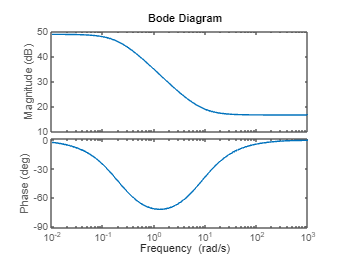

bode(Gp*Gc);

%hold on;
%plot(w_0db, 20*log10(mag(idx)), 'ro');

# Periodo de amostragem

[mag,phase,wout] = bode(Gp*Gc);

mag = squeeze(mag);
phase = squeeze(phase);
wout = squeeze(wout);

% Procurar o índice onde a magnitude é mais próxima de 1 (0 dB)
[~, idx] = min(abs(mag - 1));

% Extrair os valores correspondentes
w_0db = wout(idx);        % Frequência onde mag ≈ 0 dB
phi_0db = phase(idx);     % Fase correspondente
T = ((0.5/w_0db)+(0.15/w_0db))/2

T = 3.2500e-04



fprintf('Frequência (rad/s) onde |G| = 0 dB: %.4f\n', w_0db);

Frequência (rad/s) onde |G| = 0 dB: 1000.0000


fprintf('Fase correspondente (graus): %.3f°\n', phi_0db);

Fase correspondente (graus): -0.463°


fprintf('Periodo de amostragem: %.3f\n', T);

Periodo de amostragem: 0.000


# Digital

Gcz = c2d(Gc, T, 'tustin');
Gcz_zpk = zpk(Gcz)

Gcz_zpk =
 
  4.1323e05 (z-0.9973)
  --------------------
         (z+1)
 
Sample time: 0.000325 seconds
Discrete-time zero/pole/gain model.
Model Properties



Gpz = c2d(Gp, T, 'zoh');
Gpz_zpk = zpk(Gpz)

Gpz_zpk =
 
  3.2499e-05
  ----------
    (z-1)
 
Sample time: 0.000325 seconds
Discrete-time zero/pole/gain model.
Model Properties



Gez = Gcz *  Gpz;
Gez_zpk = zpk(Gez)

Gez_zpk =
 
  13.429 (z-0.9973)
  -----------------
     (z+1) (z-1)
 
Sample time: 0.000325 seconds
Discrete-time zero/pole/gain model.
Model Properties


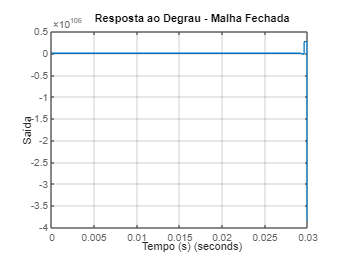


Tz = feedback(Gez, 1);  

step(Tz)
title('Resposta ao Degrau - Malha Fechada')
xlabel('Tempo (s)')
ylabel('Saída')
grid on


[y, t] = step(Tz);
ess = 1 - y(end);  % Erro em regime permanente
fprintf('Erro em regime permanente: %.6f\n', ess);

Erro em regime permanente: -12786365920457158469940853481631090450131972283140610344481905747605256959888401762439207553296439967744.000000
